% Given Data (MRI Intensity & Lesion Diameter)
mri_intensity = [180, 200, 150, 220, 210, 250]';
lesion_diameter = [30, 35, 25, 40, 38, 45]';

% Combine into a matrix
mri_data = [mri_intensity, lesion_diameter];

% Perform K-Means++ Clustering with k=2
[idx, centroids] = kmeans(mri_data, 2, 'Start', 'plus');

% Display Cluster Centers
disp('Cluster Centers:');

Cluster Centers:


disp(centroids);

  176.6667   30.0000
  226.6667   41.0000



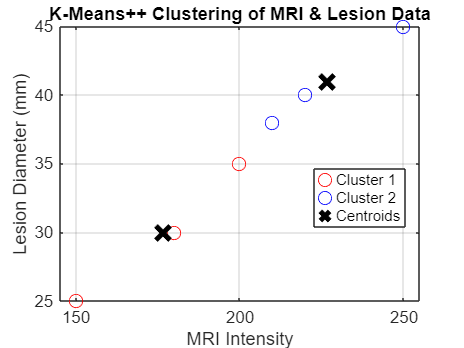


% Plot Clusters
figure;
gscatter(mri_intensity, lesion_diameter, idx, 'rb', 'o', 8);
hold on;
plot(centroids(:,1), centroids(:,2), 'kx', 'MarkerSize', 12, 'LineWidth', 3);
xlabel('MRI Intensity');
ylabel('Lesion Diameter (mm)');
title('K-Means++ Clustering of MRI & Lesion Data');
legend('Cluster 1', 'Cluster 2', 'Centroids');
grid on;
hold off;